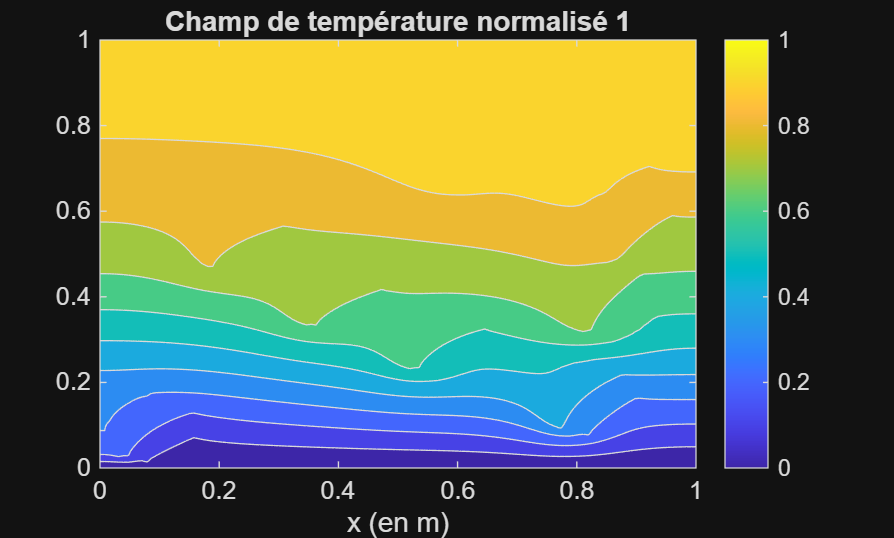


%-------------------------- Code Percolation en conduction thermique 2D--------------------------------------

%----------------------- -------------Cas hétérogène ------------------------------------------------------


clear all;
close all;

Lx = 1; %Longueur x
Ly = 1; %Longueur y
r = 10; % Rayon des charges
fs = 0.2; % Fraction surfacique de charges
kc = 10; % Conductivité charges
ki = 1; % Conductivité isolant
Nx = 128; % Nb de points x
Ny = 128; %Nb de points y

% [X, f, k, dx, dy, filename] = resolutionThermique(Nx, Ny, r, fs, kc, ki, Lx, Ly);
% 
% %Tracé
% Tet=reshape(X,Ny,Nx);
% Tet = flipud(Tet); 
% contourf(0:dx:Lx, 0:dy:Ly, Tet)                     % Trace les isothermes 
% title('Champ de température normalisé')
% xlabel('x (en m)')
% 
% figure;
% Tet=reshape(X,Ny,Nx);
% Tet = flipud(Tet);                              % inverse l'ordre des lignes : la ligne 1 passe en haut du tracé
% Nlev = 300;                        % Nombre de lignes de contour voulu
% Ts = sort(Tet(:));                 % Un seul vecteur colonne, classé de la plus petite à la plus grande
% niveaux = unique(Ts(round(linspace(1,numel(Ts),Nlev))));    % Niveaux équi-répartis en surface
% contour(0:dx:Lx, 0:dy:Ly, Tet, niveaux)                     % Trace les isothermes aux niveaux choisis
% title('Champ de température normalisé')
% xlabel('x (en m)')
% 
% 
% S = LoadMatrix(filename);
% figure;
% imagesc(full(S));
% colormap(hot);
% 
% 
% % Calcul du flux
% % On calcule le flux sur chaque ligne
% 
% Phi = sum((k(1:Ny-1,:).*(Tet(2:Ny,:)-Tet(1:Ny-1,:)))*(dx/dy),2)

[kl, f, filename]= PercolationGenerator(Nx, Ny, r, fs, false); %Conductivité thermique
[X, k, dx, dy] = resolutionThermique(Nx, Ny, kl, kc, ki, Lx, Ly);

%Tracé
Tet=reshape(X,Ny,Nx);
Tet = flipud(Tet); 
contourf(0:dx:Lx, 0:dy:Ly, Tet)                     % Trace les isothermes 
title('Champ de température normalisé 1')
xlabel('x (en m)')
colorbar();

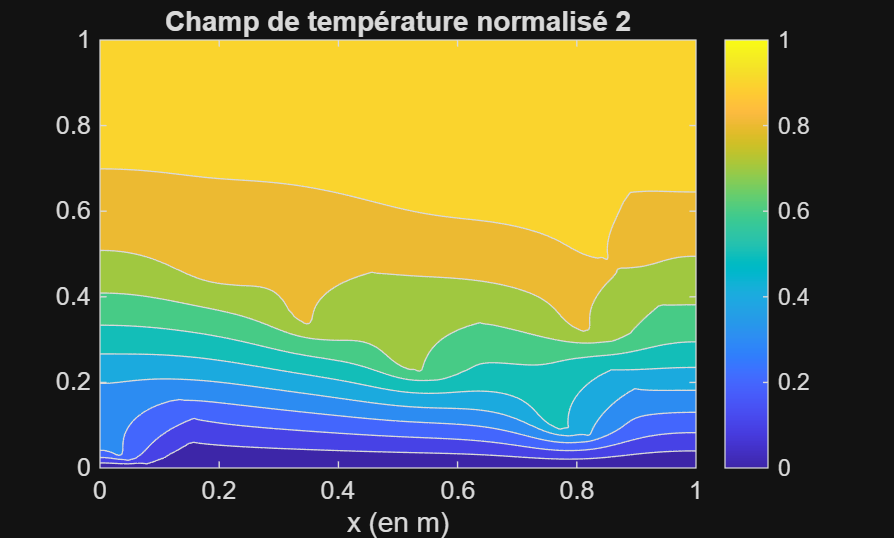


[X, k, dx, dy] = resolutionThermique(Nx, Ny, kl, kc*10, ki, Lx, Ly);

%Tracé
Tet=reshape(X,Ny,Nx);
Tet = flipud(Tet); 
contourf(0:dx:Lx, 0:dy:Ly, Tet)                     % Trace les isothermes 
title('Champ de température normalisé 2')
xlabel('x (en m)')
colorbar();

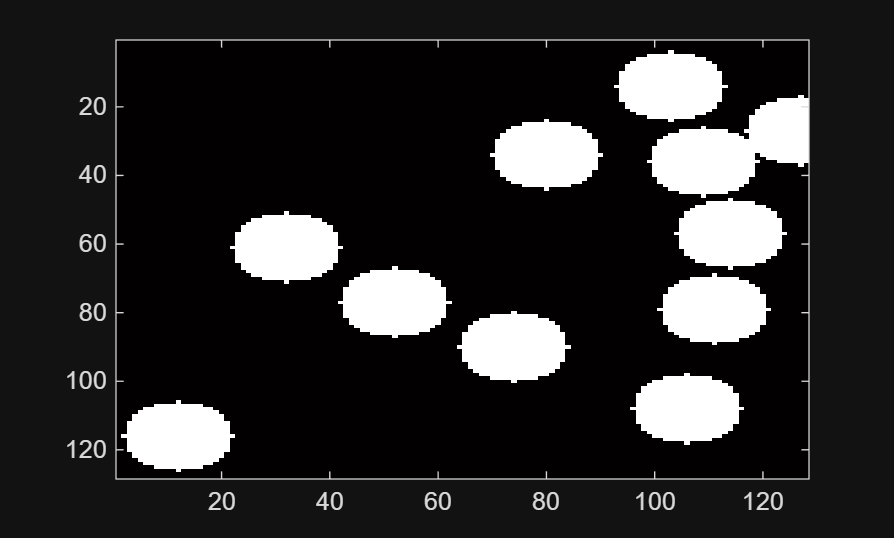


figure;
imagesc(kl);
colormap(hot);